HW 2.

******************************************************************************************************************

Background information

******************************************************************************************************************

We are interested in the relation between the average bid-ask spreads on

stocks and the characteristics of the corresponding companies. 

The data file lab2.xls contains information for the 100 stocks in the S$\&$P 100 index. 

Our variable of interest (the $Y$ variable) is the bid-ask spread

(constructed as an average over the day) - or tradecost - of the

S\&P100 stocks. The explanatory, or $X$, variables are:

- log volatility - The log of the daily return standard deviation

- log size - The log of the size of the stock. Size is total outstanding

- number of shares multiplied by share price. Size is measured in thousands of dollars

- log trades - This is the log of the average number of trades per day

- log turn - This is the log of the ratio of the average number of shares traded per day (in dollars) over the number of shares outstanding (in dollars

- NumberAnalysts - This is the number of analysts following the stock

Consider the following theories of the determinants of bid-ask spreads.

1. {Asymmetric information}. Stocks with greater degrees of asymmetry in information (regarding their fundamental value) tend to have wider bid-ask spreads. The number of analysts following a stock is viewed as an asymmetric information proxy. The larger it is, the lower private information, the smaller the spreads. Log turn-over is, also, seen as an asymmetric information proxy. The larger it is, the larger private information, the larger the spreads. Trading rates in excess of this proportion should be associated with informed trading.)

2. {Liquidity}. Stocks that trade more frequently and have larger market capitalization (i.e., more liquid stocks) tend to have lower bid-ask spreads. The larger log trades and log size, the larger liquidity, the smaller the spreads. Log turn-over is, also, sometimes seen as a liquidity proxy. The larger it is, the larger liquidity, the smaller the spreads. 

3. {Fundamental volatility}. Stocks that have a higher volatility of fundamental values tend to have larger bid-ask spreads. Higher uncertainty about the underlying stock's value implies higher potential for adverse price moves and, hence, higher inventory risk, mostly in the presence of large imbalances to offset.

The greater the degree of asymmetric information, the wider the spreads should be as the market makers (who are not fully informed) charge a higher price when selling (raising the ask) and a lower price when buying(lowering the bid) to insulate themselves from losing money to potentially etter informed traders. We do not get to see the degree of asymmetric information between market participants but we do know the following: 

1) The larger the number of analysts following a stock, the lower asymmetric information we expect to be for that stock. Analysts provide informationabout the stock, thereby uncovering its fundamental value. 

2) The greater the turn-over of the stock, the higher we expect asymmetric information to be for that stock. Intuitively, the greater the turnover, the faster individuals are getting in and out of investment positions in the stock. They do this more when they believe the current price does not accurately reflect the fundamental value of the stock - that is, when they believe theypossess asymmetric (superior) information. 

As indicated, turn-over is also viewed, by some, as a liquidity proxy.

************************************************************************************************8

Instructions:

a. You will answer a set of questions that will require to analyze data and run/set-up  multivariate regressions.

b. The file is organized in block, with text setting up a question, then an area where you insdert your code, and then a text area wehre you insdert your comments and answers

c. Once you complete the analysis, you will submit a .pdf file that reports your code, your results, and you ansers to the questions (marked with Q).

***************************************

Q1 (2 points). Import the data set and set up variable names

% import dataset lab2.xls (using Import Dataset)


***************************************

Q2. (2 points) Generate a historgram of  the bid-ask spread and the log of the bid-ask spread (tradecost).

What are their diffrences?

tradecost = lab2{ : ,1};
h1 = histogram(tradecost, 50)
logtradecost = log(lab2{ : ,1});
h2 = histogram(logtradecost, 50)

Answer:

***********************************************

Q3.(5 points) Run a regression of the log of the bid-ask spread on the 5 explanatory variables.

Interpret the sign of the estimated coefficients of the 5 explanatory variables in light of the theories outlined in the background information.

lm = fitlm(lab2{ : , 2:6}, logtradecost)

Answer:

Q4. (4 points) Organize the data in matrix format, and compute the regression coefficients using the OLS formulas for these coefficients  in matrix form. Check that you obtain the same results of those obtained with the fitlm command.

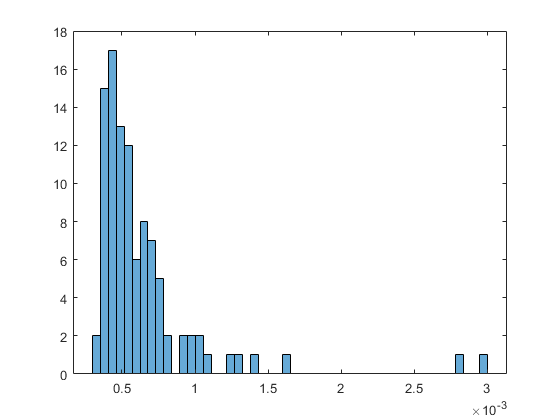

h1 =   Histogram with properties:

             Data: [100×1 double]
           Values: [2 15 17 13 12 6 8 7 5 2 0 2 2 2 1 0 0 1 1 0 1 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 5.4000e-05
        BinLimits: [3.0000e-04 0.0030]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


x =  lab2{ : ,2:6};

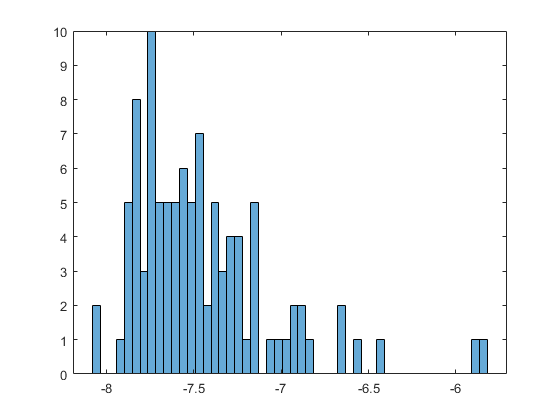

h2 =   Histogram with properties:

             Data: [100×1 double]
           Values: [2 0 0 1 5 8 3 10 5 5 5 6 5 7 2 5 3 4 4 1 5 0 1 1 1 2 2 1 0 0 0 2 0 1 0 0 1 0 0 0 0 0 0 0 0 0 0 0 1 1]
          NumBins: 50
         BinEdges: [1×51 double]
         BinWidth: 0.0452
        BinLimits: [-8.0800 -5.8200]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


x = [ones(100,1), x];
coef = inv(x.'*x)*x.'*logtradecost

Answer:

*************************************************

Q5. Test the null that all coefficients are 0.

[p1,F1,r1] = coefTest(lm)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

Estimated Coefficients:
                   Estimate        SE         tStat        pValue  
                   _________    _________    ________    __________

    (Intercept)     -0.82932      0.44277      -1.873      0.064173
    x1                 1.023     0.053245      19.213     2.574e-34
    x2              -0.14029      0.02391     -5.8673    6.5918e-08
    x3              -0.16936     0.035596      -4.758    7.0564e-06
    x4             -0.098714     0.032502     -3.0371     0.0030911
    x5             5.044e-05    0.0029135    0.017313       0.98622


Number of observations: 100, Error degrees of freedom: 94
Root Mean Squared Error: 0.142
R-squared: 0.882,  Adjusted R-Square

Answer:

*************************************************

Q6. Test the assumption that the coefficients associated with Logsize and Logtrades are equal to each other.

H = [0 0 1 -1 0 0];
[p2,F2,r2] = coefTest(lm, H)

Answer:

*************************************************

Q7. Test the assumption that the coefficients associated with logturnover and the number of analysts are jointly equal to zero.

H = [0 0 0 0 1 0; 0 0 0 0 0 1];

coef =    -0.8293
    1.0230
   -0.1403
   -0.1694
   -0.0987
    0.0001


[p3,F3,r3] = coefTest(lm, H)

p1 = 4.1630e-42

F1 = 141.1555

r1 = 5

p2 = 0.5032

F2 = 0.4516

r2 = 1

p3 = 0.0088

F3 = 4.9792

r3 = 2

Answer:

*************************************************